# Práctica 5 - GNSS

#### Maria José Medina y Teresa González

## Introducción

En esta práctica se han trabajado con el sistema de localización GNSS. En particular, se han realizado dos apartados

- Cálculo de la posición x,y, z de un terminal a partir de la posición de un conjunto de satélites, partiendo de unas coordenadas geodésicas iniciales

- Cálculo de las coordenadas geódesicas a partir de las coordenadas x, y, z obtenidas en el apartado anterior

## Parte 1 - Determinación de coordenadas cartesianas (x y z) del terminal

A partir la posición y tiempo relativo (diferencia respecto a la referencia interna del terminal) de llegada de 5 satélites, se calculan las coordenadas x, y, z de un terminal móvil, suponiendo que todos los satélites transmiten simultáneamente. Las coordenadas de los satélites se consideran exactas mientras que las de los tiempos de llegada contienen un error aleatorio inferior a  +/-20 ns, ya que los relojes no son atómicos. Para ello se calcula la distancia entre los satélites y el terminal, así como la matriz de diferencia de gradientes y la diferencia de distancias entre ellos. Para calcular la posición se realizan varias iteraciones con el fin de minimizar el MSE (error cuadrático medio) de dicha posición mediante el método de Mooose-Penrose: 


$$\Delta r 
= ([A]'\cdot [A])^{-1}\cdot [A]'\cdot [\rho ]                      $$


Siendo A la matriz diferencia de gradientes de las distancias y $\rho =c\cdot \left(t_i -t_j \right)-\left(d_i -d_j \right)$. Finalmente, la posición será r= ro + $\Delta r$, es decir,, la posición inicial + el incremento de la posición. 

En este caso, se utiliza como posición inicial las coordenadas geodésicas de un punto de Madrid:

- lat=40.3º

- long=-3.4º

- altura=0.667 (km)

% Datos iniciales de partida
%  % t_relativo de      coordenadas xyz del satélite
%   % llegada (ms)                  (km)
% %--------------------------------------------------------
%    4.42856        -23459.789    4017.922  11782.610
%    7.06786         -8250.272   22325.734  11782.610
%   14.01348        -12805.515  -14383.910  18288.171
%    3.23879        -18859.589    3897.946  18288.171
%    5.91472         -6054.074   18281.857  18288.171

% Coordenadas geodésicas iniciales en una posición inicial de Madrid
lat = 40.3;
long = -3.4;
altura = 0.667; % km

c = 3*10^8;

% datos sat = [t, x, y, z]
sat = [4.42856        -23459.789    4017.922  11782.610;
    7.06786         -8250.272   22325.734  11782.610;
    14.01348        -12805.515  -14383.910  18288.171;
    3.23879        -18859.589    3897.946  18288.171;
    5.91472         -6054.074   18281.857  18288.171];

% Extraccion datos
nsat = size(sat,1); % número de satélites
t_i_ms = sat(:,1); %tiempo de llegada
Rsat = sat(:, 2:end); %coordenadas en km

% Coordenadas XYZ con la función dada
ro = r_antena_km(altura, lat, long);

%Matriz diferencia de tiempos
t_sat = zeros(nsat-1,1);

%Bucle diferencia de tiempos con respecto a t1
for l = 1:nsat-1
    t_sat(l,1) = t_i_ms(l+1)-t_i_ms(1);
end

t_sat = t_sat*1e-3; % en segundos

%Matriz diferencia de distancias
mat_d = zeros(nsat-1,1);

%Error inicial
error=1;

% Bucle iteraciones para calcular la diferencia de distancias
while error > 10^-11

    % distancia euclídea entre satelites y terminal
    d=zeros(nsat,length(ro));
    d = vecnorm(Rsat- ro, 2, 2);

    %Bucle diferencia de distancias con respecto a d1
    for l = 1:nsat-1
        mat_d(l,1) = d(l+1)-d(1);
    end

    % Matriz diferencia de gradientes con respecto a d1
    Dif_Grad = zeros(nsat-1,length(ro));
    % Bucle diferencia de gradientes
    for l=1:nsat-1
        for m = 1:3
            Dif_Grad(l,m) = -((1/d(l+1))*(Rsat(l+1,m)-ro(m)) - (1/d(1))*(Rsat(1,m) - ro(m)));
        end
    end

    %p=c*(ti-tj) - (di-dj)
    p = (c*t_sat - mat_d*10^3)*1e-3; % en km

    % Método Moose-Penrose para obtener el incremento de r (variación de la
    % posición) de una matriz no cuadrada en función de matriz Dif_Grad y p inicial
    % Incremento de distancia
    delta_r = ((Dif_Grad'*Dif_Grad)^-1)*Dif_Grad'*p;

    % Posicion terminal
    ro = ro + delta_r';
    error = abs(delta_r(1));

end

% Posicion final terminal
disp(['Posición (km): ', num2str(ro)])

Posición (km): -4151.1273      2530.6815      4114.9721


Finalmente, se observa que el bucle converge en 5 iteraciones, hasta que el error se convierte en despreciable (error en $\Delta r$ <10^-11 en km).

## Parte 2 - Determinación de coordenadas geodésicas (h lat long)

En este apartado, a partir de las coordenadas (x y z) del terminal obtenidas anteriormente, se calcula su posición en coordenadas geodésicas (lat, long y h).  Se tiene en cuenta que la Tierra tarda menos de 24 h en dar una vuelta sobre sí misma, lo que se conoce como periodo sidéreo. Este valor (23h 56 min) se obtiene observando la Tierra desde un punto lejano, ya que además de la rotación sobre sí misma también se desplaza en su órbita alrededor del Sol, y por ello el valor resultante es menor que T=24 h (periodo sinódico, observado desde la Tierra). 

Además, para transformar las coordenadas del punto anterior se tiene en cuenta que el sistema GNSS inicializó sus contadores a las 00.00 del día 1 (puntos meridiano de Greenwich corresponden a y=0), y que dichas coordenadas calculadas corresponden al día 3 a las 10.00GMT. Por ello, es necesario ajustar la longitud en función de la rotación terrestre durante el periodo de 10 horas.

Finalmente, se indicará la posición sobre un mapa de Google Maps.

% Periodo sidéreo en horas
T = 23.9344696

T = 23.9345


% Coordenadas lat long y h a partir de XYZ calculadas anteriormente -> contador GNSS inicializado a las 00:00 GMT
[h, lat_2, long_2] = r_antena_geod(ro);

% Ángulo de rotación de la tierra en radianes a las 10:00 GMT , teniendo en
% cuenta la rotación de la tierra durante las 10 horas.
theta=2*pi*(round(2*T+10))/T;

% Incremento de la longitud con respecto a la inicial (00:00 GMT)
inc_long=theta-round(theta/(2*pi))*2*pi;

%Ajuste en la longitud tras rotación tierra
long_2=long_2-inc_long;


% Coordenadas geodésicas resultantes:
coord=[lat_2*180/pi long_2*180/pi];
disp(['Altura: ', num2str(h), ' km']);

Altura: 0.60601 km


disp(['Latitud: ', num2str(coord(1)), ' º']);

Latitud: 40.4401 º


disp(['Longitud: ', num2str(coord(2)), ' º']);

Longitud: -3.75 º


A continuación, se representa la diferencia en coordenadas geodésicas tras la rotación de la tierra (10:00 GMT). Se observa que tanto la latitud como la longitud han cambiado, siendo la diferencia en latitud de 0.14007 º y en longitud de -0.35002º. Por ello, el cálculo de la posición del terminal se ha corregido ligeramente hacia el norte y hacia el oeste.

% Incremento en lat y long
disp(['Diferencia en Latitud: ', num2str(coord(1)-lat), ' º']);

Diferencia en Latitud: 0.14007 º


disp(['Diferencia en Longitud: ', num2str(coord(2)-long), ' º']);

Diferencia en Longitud: -0.35002 º


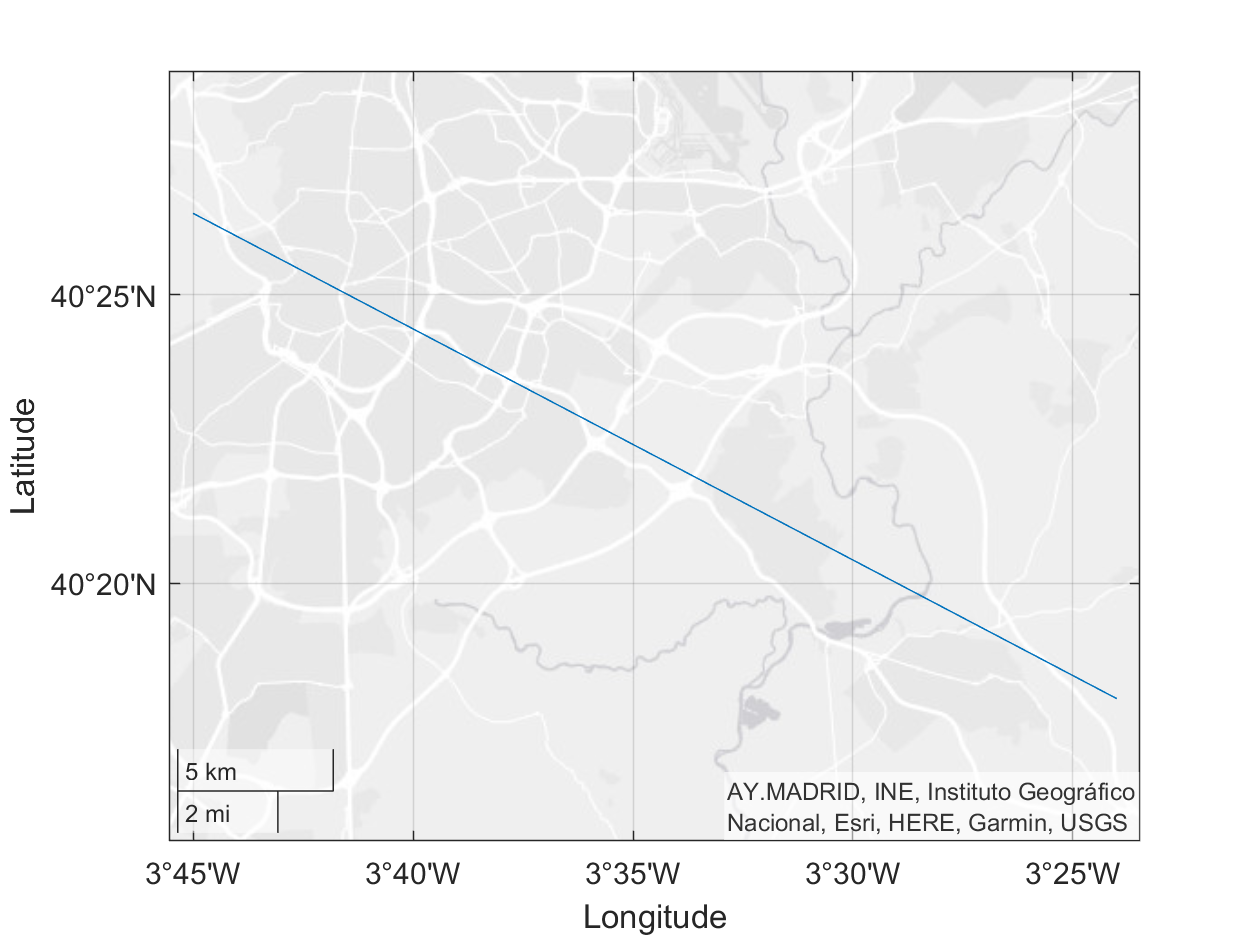

geoplot([lat coord(1)],[long coord(2)]);

Se obtiene con Google Maps el punto geográfico correspondiente a la posición del terminal, que corresponde a la zona Moncloa- Aravaca:

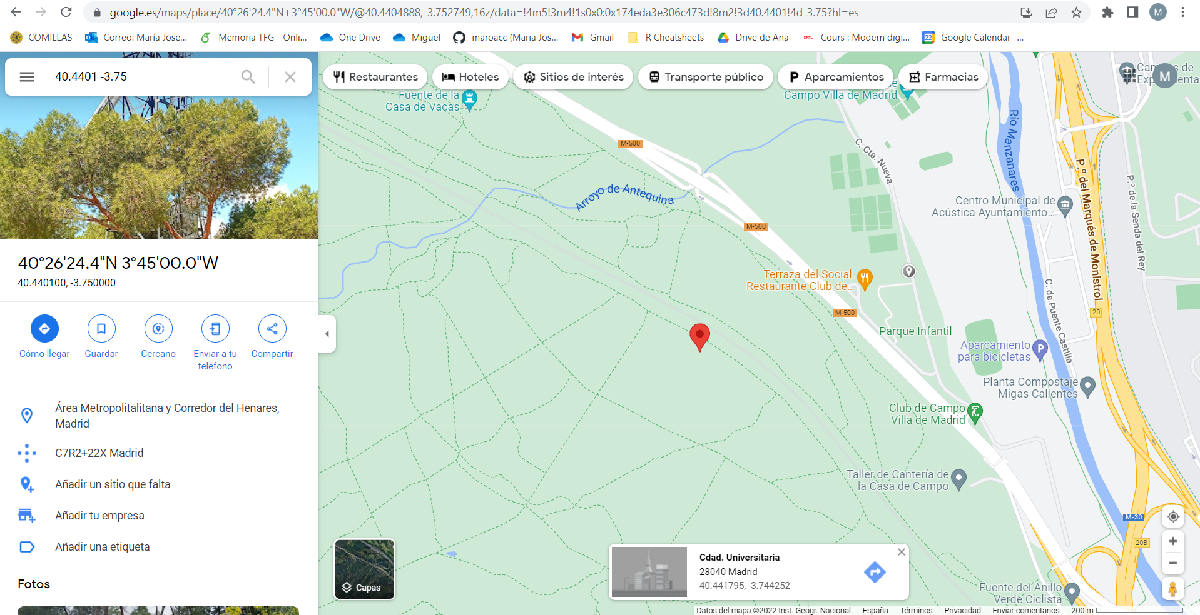

Enlace: [https://www.google.es/maps/place/40%C2%B026'24.4%22N+3%C2%B045'00.0%22W/@40.4404888,-3.752749,16z/data=!4m5!3m4!1s0x0:0x174eda3e306c473d!8m2!3d40.4401!4d-3.75?hl=es](https://www.google.es/maps/place/40%C2%B026%2724.4%22N+3%C2%B045%2700.0%22W/@40.4404888,-3.752749,16z/data=!4m5!3m4!1s0x0:0x174eda3e306c473d!8m2!3d40.4401!4d-3.75?hl=es)